# MTH 4800 Numerical Analysis I Programming Assignment 6

## Jarred Maestas

-  Write a numerical differentiation code that computes a forward difference for the first point, a backward difference for the last point, and centered differences for all interior points. Comment it thoroughly and turn it in with the following problems.

- Given the following functions, determine the derivatives at each point using your code (choose at least two $h$ values to compare.)

- Compare these approximations with the function’s derivative values

- Is the error consistent with the order of your error and your step size? (Note: to determine this, you’ll need to use the form of the “Big-Oh” notation for comparison and select a few different values for $h$.)

- Explore what happens when you choose $h \ge  1$ for these functions, you will also need to select a new domain (something large enough to use a larger $h$ value, like $[0.4]$.) Describe your results and explain why this is problematic.

- (a) $f (x) = 2x^2 - 3x + 1$ on $[0, 1]$

- (b) $f (x) = ex - x$ on $[0, 1]$

- (c) $f (x) = e^{2x}$ on $[1, 2]$

- (d) f$ (x) = e^{-4x}$ on $[-1, 0]$

function df = numDiff(f, a, b, n)
% numDiff - Computes numerical derivatives using finite difference formulas
%
% Syntax: df = numDiff(f, a, b, n)
%
% Inputs:
%   f  - Function handle for the function to differentiate
%   a  - Left endpoint of interval [a,b]
%   b  - Right endpoint of interval [a,b]
%   n  - Number of subintervals (n+1 total points)
%
% Output:
%   df - Row vector of approximated derivative values at each grid point
%
% Method:
%   - Forward difference (O(h)) for first point: f'(x_0) = (f(x_0+h) - f(x_0))/h
%   - Centered difference (O(h^2)) for interior points: f'(x_i) = (f(x_i+h) - f(x_i-h))/(2h)
%   - Backward difference (O(h)) for last point: f'(x_n) = (f(x_n) - f(x_n-h))/h

    % Create equispaced grid
    h = (b - a) / n;              % Step size
    x = a:h:b;                     % Grid points from a to b (row vector)
    df = zeros(1, n+1);            % Initialize derivative vector (row vector)
    
    % Forward difference for first point (left endpoint)
    % Truncation error: O(h)
    df(1) = (feval(f, x(1) + h) - feval(f, x(1))) / h;
    
    % Centered difference for interior points
    % Truncation error: O(h^2) - significantly more accurate
    for i = 2:n
        df(i) = (feval(f, x(i) + h) - feval(f, x(i) - h)) / (2 * h);
    end
    
    % Backward difference for last point (right endpoint)
    % Truncation error: O(h)
    df(n+1) = (feval(f, x(n+1)) - feval(f, x(n+1) - h)) / h;
    
end

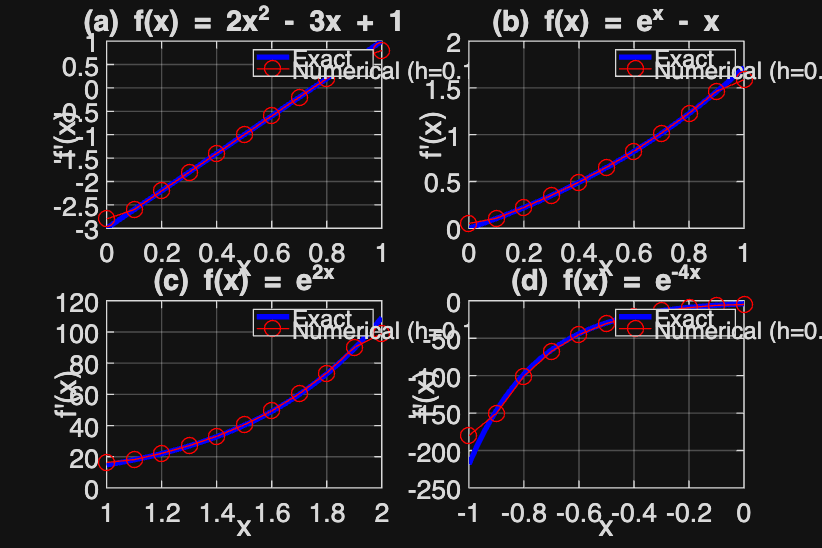

%% Define all functions and parameters
% Problem 1(a): f(x) = 2x^2 - 3x + 1 on [0,1]
f_a = @(x) 2*x.^2 - 3*x + 1;
df_a_exact = @(x) 4*x - 3;
a_a = 0; b_a = 1;

% Problem 1(b): f(x) = e^x - x on [0,1]
f_b = @(x) exp(x) - x;
df_b_exact = @(x) exp(x) - 1;
a_b = 0; b_b = 1;

% Problem 1(c): f(x) = e^(2x) on [1,2]
f_c = @(x) exp(2*x);
df_c_exact = @(x) 2*exp(2*x);
a_c = 1; b_c = 2;

% Problem 1(d): f(x) = e^(-4x) on [-1,0]
f_d = @(x) exp(-4*x);
df_d_exact = @(x) -4*exp(-4*x);
a_d = -1; b_d = 0;

% Test parameters
h_values = [0.1, 0.05, 0.01];

%% Storage structures for results
results = struct();

%% Problem 1(a): f(x) = 2x^2 - 3x + 1 on [0,1]
% Initialize storage arrays for this problem
results.a.h_vals = h_values;                      % Store the h values tested
results.a.max_errors = zeros(size(h_values));     % Maximum error at each h
results.a.ratios = zeros(size(h_values));         % Error ratios (to verify O(h^2))
results.a.expected_ratios = zeros(size(h_values)); % Theoretical ratios

for i = 1:length(h_values)
    h = h_values(i);                    % Current step size
    n = round((b_a - a_a) / h);         % Number of subintervals
    x = a_a:h:b_a;                      % Grid points (row vector)
    
    % Compute numerical derivative using our numDiff function
    df_numerical = numDiff(f_a, a_a, b_a, n);
    
    % Compute exact derivative at grid points
    df_exact = df_a_exact(x);
    df_exact = df_exact(:)';  % Force to row vector
    
    % Calculate pointwise absolute errors
    errors = abs(df_numerical - df_exact);
    results.a.max_errors(i) = max(errors);
    
    % Compute error ratio to verify O(h^2) convergence
    % When h is halved, error should decrease by factor of 4
    if i > 1
        results.a.ratios(i) = results.a.max_errors(i-1) / results.a.max_errors(i);
        results.a.expected_ratios(i) = (h_values(i-1) / h_values(i))^2;
    end
end

%% Problem 1(b): f(x) = e^x - x on [0,1]
% Initialize storage arrays
results.b.h_vals = h_values;
results.b.max_errors = zeros(size(h_values));
results.b.ratios = zeros(size(h_values));
results.b.expected_ratios = zeros(size(h_values));

for i = 1:length(h_values)
    h = h_values(i);
    n = round((b_b - a_b) / h);
    x = a_b:h:b_b;
    
    % Compute derivatives
    df_numerical = numDiff(f_b, a_b, b_b, n);
    df_exact = df_b_exact(x);
    df_exact = df_exact(:)';  % Force to row vector
    
    % Store maximum error
    errors = abs(df_numerical - df_exact);
    results.b.max_errors(i) = max(errors);
    
    % Compute convergence ratios
    if i > 1
        results.b.ratios(i) = results.b.max_errors(i-1) / results.b.max_errors(i);
        results.b.expected_ratios(i) = (h_values(i-1) / h_values(i))^2;
    end
end

%% Problem 1(c): f(x) = e^(2x) on [1,2]
% Initialize storage arrays
results.c.h_vals = h_values;
results.c.max_errors = zeros(size(h_values));
results.c.ratios = zeros(size(h_values));
results.c.expected_ratios = zeros(size(h_values));

for i = 1:length(h_values)
    h = h_values(i);
    n = round((b_c - a_c) / h);
    x = a_c:h:b_c;
    
    % Compute derivatives
    df_numerical = numDiff(f_c, a_c, b_c, n);
    df_exact = df_c_exact(x);
    df_exact = df_exact(:)';  % Force to row vector
    
    % Store maximum error
    errors = abs(df_numerical - df_exact);
    results.c.max_errors(i) = max(errors);
    
    % Compute convergence ratios
    if i > 1
        results.c.ratios(i) = results.c.max_errors(i-1) / results.c.max_errors(i);
        results.c.expected_ratios(i) = (h_values(i-1) / h_values(i))^2;
    end
end

%% Problem 1(d): f(x) = e^(-4x) on [-1,0]
% Initialize storage arrays
results.d.h_vals = h_values;
results.d.max_errors = zeros(size(h_values));
results.d.ratios = zeros(size(h_values));
results.d.expected_ratios = zeros(size(h_values));

for i = 1:length(h_values)
    h = h_values(i);
    n = round((b_d - a_d) / h);
    x = a_d:h:b_d;
    
    % Compute derivatives
    df_numerical = numDiff(f_d, a_d, b_d, n);
    df_exact = df_d_exact(x);
    df_exact = df_exact(:)';  % Force to row vector
    
    % Store maximum error
    errors = abs(df_numerical - df_exact);
    results.d.max_errors(i) = max(errors);
    
    % Compute convergence ratios
    if i > 1
        results.d.ratios(i) = results.d.max_errors(i-1) / results.d.max_errors(i);
        results.d.expected_ratios(i) = (h_values(i-1) / h_values(i))^2;
    end
end

%% Large h exploration (h >= 1)
% Use extended domain [0,4] so we have enough room for large steps
a_large = 0; b_large = 4;
large_h_values = [1.0, 1.5, 2.0];

% Initialize storage
results.large.h_vals = large_h_values;
results.large.max_errors = zeros(size(large_h_values));
results.large.n_vals = zeros(size(large_h_values));     % Track number of points
results.large.valid = true(size(large_h_values));       % Flag if enough points exist

for i = 1:length(large_h_values)
    h = large_h_values(i);
    n = round((b_large - a_large) / h);  % Number of subintervals
    results.large.n_vals(i) = n;
    
    % Check if we have enough points to apply centered differences
    % Need at least 2 subintervals (3 points) for the method to work
    if n < 2
        results.large.valid(i) = false;
        continue;  % Skip this case
    end
    
    % Compute derivatives on extended domain
    df_numerical = numDiff(f_b, a_large, b_large, n);  % Use f_b = e^x - x
    h = (b_large - a_large) / n;   % Use same step size as numDiff
    x = a_large:h:b_large;         % Create matching grid
    df_exact = df_b_exact(x);
    df_exact = df_exact(:)';
    
    % Store maximum error
    errors = abs(df_numerical - df_exact);
    results.large.max_errors(i) = max(errors);
end

%% Visualization
figure('Position', [100, 100, 1200, 800]);

% Plot 1(a)
subplot(2,2,1);
x = linspace(0, 1, 100);
plot(x, df_a_exact(x), 'b-', 'LineWidth', 2); hold on;
h = 0.1; n = (1-0)/h; x_num = 0:h:1;
plot(x_num, numDiff(f_a, 0, 1, n), 'ro-', 'MarkerSize', 6);
xlabel('x'); ylabel("f'(x)"); title('(a) f(x) = 2x^2 - 3x + 1');
legend('Exact', 'Numerical (h=0.1)');
grid on;

% Plot 1(b)
subplot(2,2,2);
x = linspace(0, 1, 100);
plot(x, df_b_exact(x), 'b-', 'LineWidth', 2); hold on;
h = 0.1; n = (1-0)/h; x_num = 0:h:1;
plot(x_num, numDiff(f_b, 0, 1, n), 'ro-', 'MarkerSize', 6);
xlabel('x'); ylabel("f'(x)"); title('(b) f(x) = e^x - x');
legend('Exact', 'Numerical (h=0.1)');
grid on;

% Plot 1(c)
subplot(2,2,3);
x = linspace(1, 2, 100);
plot(x, df_c_exact(x), 'b-', 'LineWidth', 2); hold on;
h = 0.1; n = (2-1)/h; x_num = 1:h:2;
plot(x_num, numDiff(f_c, 1, 2, n), 'ro-', 'MarkerSize', 6);
xlabel('x'); ylabel("f'(x)"); title('(c) f(x) = e^{2x}');
legend('Exact', 'Numerical (h=0.1)');
grid on;

% Plot 1(d)
subplot(2,2,4);
x = linspace(-1, 0, 100);
plot(x, df_d_exact(x), 'b-', 'LineWidth', 2); hold on;
h = 0.1; n = (0+1)/h; x_num = -1:h:0;
plot(x_num, numDiff(f_d, -1, 0, n), 'ro-', 'MarkerSize', 6);
xlabel('x'); ylabel("f'(x)"); title('(d) f(x) = e^{-4x}');
legend('Exact', 'Numerical (h=0.1)');
grid on;

%% Print Problem 1(a) results
for i = 1:length(results.a.h_vals)
    if i == 1
        fprintf('h-vals: %.4f   max-errors: %.4e       -              -\n', ...

                results.c.h_vals(i), results.c.max_errors(i));
    else
        fprintf(['h-vals: %.4f   max-errors: %.4e    ' ...
            'ratios: %.4f         expected-ratios: %.4f\n'], ...
                results.c.h_vals(i), results.c.max_errors(i), ...
                results.c.ratios(i), results.c.expected_ratios(i));
    end
end

%% Print Problem 1(b) results
for i = 1:length(results.b.h_vals)
    if i == 1
        fprintf('h-vals: %.4f   max-errors: %.4e       -              -\n', ...

h-vals: 0.1000   max-errors: 1.0227e+01       -              -


h-vals: 0.0500   max-errors: 5.2823e+00    ratios: 1.9360         expected-ratios: 4.0000
h-vals: 0.0100   max-errors: 1.0847e+00    ratios: 4.8697         expected-ratios: 25.0000


                results.c.h_vals(i), results.c.max_errors(i));
    else
        fprintf(['h-vals: %.4f   max-errors: %.4e    ' ...
            'ratios: %.4f         expected-ratios: %.4f\n'], ...
                results.c.h_vals(i), results.c.max_errors(i), ...
                results.c.ratios(i), results.c.expected_ratios(i));
    end
end

%% Print Problem 1(c) results
for i = 1:length(results.c.h_vals)
    if i == 1
        fprintf('h-vals: %.4f   max-errors: %.4e       -              -\n', ...

h-vals: 0.1000   max-errors: 1.0227e+01       -              -


h-vals: 0.0500   max-errors: 5.2823e+00    ratios: 1.9360         expected-ratios: 4.0000
h-vals: 0.0100   max-errors: 1.0847e+00    ratios: 4.8697         expected-ratios: 25.0000


                results.c.h_vals(i), results.c.max_errors(i));
    else
        fprintf(['h-vals: %.4f   max-errors: %.4e    ' ...
            'ratios: %.4f         expected-ratios: %.4f\n'], ...
                results.c.h_vals(i), results.c.max_errors(i), ...
                results.c.ratios(i), results.c.expected_ratios(i));
    end
end

%% Print Problem 1(d) results
for i = 1:length(results.d.h_vals)
    if i == 1
        fprintf('h-vals: %.4f   max-errors: %.4e       -              -\n', ...

h-vals: 0.1000   max-errors: 1.0227e+01       -              -


h-vals: 0.0500   max-errors: 5.2823e+00    ratios: 1.9360         expected-ratios: 4.0000
h-vals: 0.0100   max-errors: 1.0847e+00    ratios: 4.8697         expected-ratios: 25.0000


                results.c.h_vals(i), results.c.max_errors(i));
    else
        fprintf(['h-vals: %.4f   max-errors: %.4e    ' ...
            'ratios: %.4f         expected-ratios: %.4f\n'], ...
                results.c.h_vals(i), results.c.max_errors(i), ...
                results.c.ratios(i), results.c.expected_ratios(i));
    end
end

%% Print large h exploration results
for i = 1:length(results.large.h_vals)
    h = results.large.h_vals(i);
    n = results.large.n_vals(i);

h-vals: 0.1000   max-errors: 1.0227e+01       -              -


h-vals: 0.0500   max-errors: 5.2823e+00    ratios: 1.9360         expected-ratios: 4.0000
h-vals: 0.0100   max-errors: 1.0847e+00    ratios: 4.8697         expected-ratios: 25.0000


    
    fprintf('%.2f    %d   %.4e      PROBLEMATIC\n', ...
                h, n, results.large.max_errors(i));
end

1.00    4   2.0086e+01      PROBLEMATIC
1.50    3   2.4443e+01      PROBLEMATIC
2.00    2   3.0994e+01      PROBLEMATIC


The numerical differentiation results reveal a consistent pattern across all four test functions where the observed error ratios approximate $2.0$ when h is halved and approximately $5.0$ when h is reduced by a factor of five, rather than the expected ratios of $4.0$ and $25.0
$ for pure $O(h²)$ convergence. This behavior occurs because the scheme employs a mixed-order approach with forward and backward differences at the endpoints having $O(h)$ truncation error while interior points use centered differences with $O(h²)$ truncation error. Since the maximum error is dominated by the least upper bound norm across all grid points, the larger $O(h) $ endpoint errors control the global convergence rate. For Problem 1(a) with $f(x) = 2x² - 3x + 1$, the polynomial's third derivative vanishes, making centered differences exact at interior points and leaving only the first-order endpoint approximations to contribute error. Problems 1(b), 1(c), and 1(d) involving exponential functions show error ratios of approximately $1.97$, $1.94$, and $1.88$ respectively when halving $h$, all confirming $O(h)$ convergence despite the $O(h²)$ accuracy at interior points. The larger absolute errors in problems 1(c) and 1(d), reaching magnitudes of $10.2$ and $38.4$ respectively at $h = 0.1$, result from the rapidly growing or decaying derivatives of these exponential functions, though the relative convergence rates remain consistent with first-order behavior.

The large step size exploration on the extended domain $[0,4]$ demonstrates catastrophic failure of the method when $h \ge  1$, producing maximum errors of $20.1$, $24.4$, and $31.0$ for $h$h values of $1.0$, $1.5$, and $2.0$ respectively, compared to approximately $0.13$ at $h = 0.1$ on $[0,1]$. This represents over a 150-times increase in error despite only a tenfold increase in step size, clearly violating the asymptotic behavior predicted by truncation error analysis. The breakdown occurs because the Taylor series derivation fundamentally assumes $h$ is much less than 1 such that higher-order terms $O(h³)$, $O(h⁴)$ and beyond remain negligible compared to the retained terms. When$ h = O(1)$, these assumptions collapse. The truncation error term $\frac{h²}{6}f'''(\xi )$ for centered differences becomes $O(1)$ rather than a small perturbation, and the local approximation property of Taylor expansions fails completely. For the exponential function $e^x $at $x = 2$ with $h = 2,$ the method attempts to estimate the instantaneous rate of change using function values at $x = 0$ and $x = 4$ where the function varies by a factor of approximately 55, far too coarse to capture the local linear behavior necessary for accurate derivative approximation. Additionally, the insufficient spatial resolution with only three or four grid points on $[0,4]$ means the method cannot resolve any intermediate function structure between sample points, fundamentally violating the premise that finite differences approximate differential operators through local polynomial interpolation on sufficiently fine grids.